### Set up workspace 

clearvars
addpath('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')
addpath('C:\Users\fogaren\Desktop')
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')

### Calculate oxygen sensor lag for CTD alignment 

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year8')

% % Casts 
cast01 = readSBScnv( 'ar60-1_001_hyst.cnv' );
cast02 = readSBScnv( 'ar60-1_002_hyst.cnv');
cast03 = readSBScnv( 'ar60-1_003_hyst.cnv' );
cast04 = readSBScnv( 'ar60-1_004_hyst.cnv' );
cast05 = readSBScnv( 'ar60-1_005_hyst.cnv' );
cast06 = readSBScnv( 'ar60-1_006_hyst.cnv' );
cast07 = readSBScnv( 'ar60-1_007_hyst.cnv' );
cast08 = readSBScnv( 'ar60-1_008_hyst.cnv' );
cast09 = readSBScnv( 'ar60-1_009_hyst.cnv' );
cast10 = readSBScnv( 'ar60-1_010_hyst.cnv' );
cast11 = readSBScnv( 'ar60-1_011_hyst.cnv' );
cast12 = readSBScnv( 'ar60-1_012_hyst.cnv' );

% % Casts _nohyst
% cast01 = readSBScnv( 'ar60-1_001_nohyst.cnv' );
% cast02 = readSBScnv( 'ar60-1_002_nohyst.cnv');
% cast03 = readSBScnv( 'ar60-1_003_nohyst.cnv' );
% cast04 = readSBScnv( 'ar60-1_004_nohyst.cnv' );
% cast05 = readSBScnv( 'ar60-1_005_nohyst.cnv' );
% cast06 = readSBScnv( 'ar60-1_006_nohyst.cnv' );
% cast07 = readSBScnv( 'ar60-1_007_nohyst.cnv' );
% cast08 = readSBScnv( 'ar60-1_008_nohyst.cnv' );
% cast09 = readSBScnv( 'ar60-1_009_nohyst.cnv' );
% cast10 = readSBScnv( 'ar60-1_010_nohyst.cnv' );
% cast11 = readSBScnv( 'ar60-1_011_nohyst.cnv' );
% cast12 = readSBScnv( 'ar60-1_012_nohyst.cnv' );

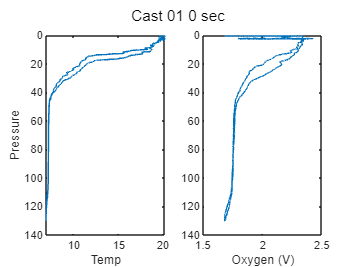

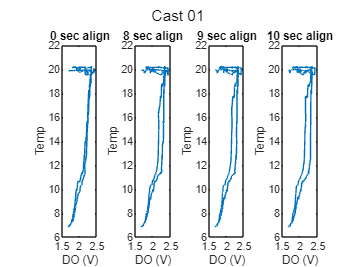

% cast = alignCTD_KF(cast,CastString,a1,a2,a3) % Function
a1 = 8; a2 = 9; a3 = 10;

cast01 = align_CTD_KF(cast01,'Cast 01',a1,a2,a3);

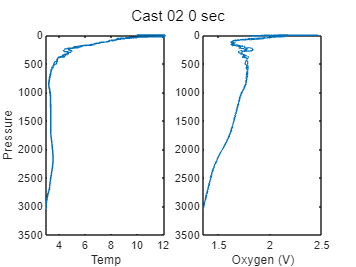

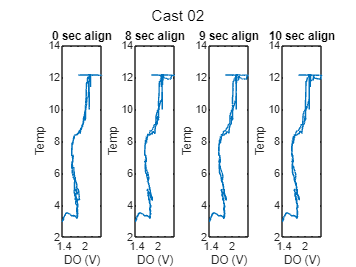

cast02 = align_CTD_KF(cast02,'Cast 02',a1,a2,a3);

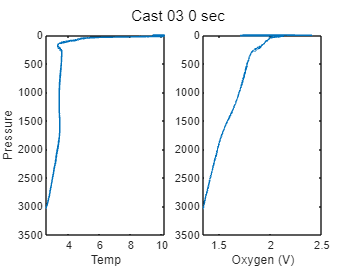

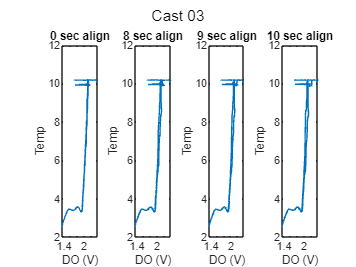

cast03 = align_CTD_KF(cast03,'Cast 03',a1,a2,a3);

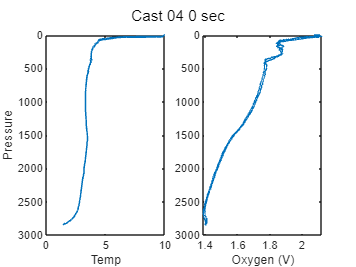

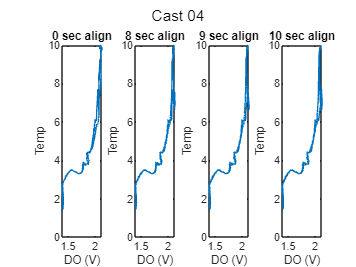

cast04 = align_CTD_KF(cast04,'Cast 04',a1,a2,a3);

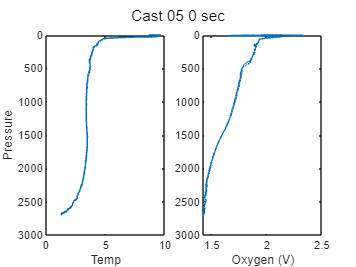

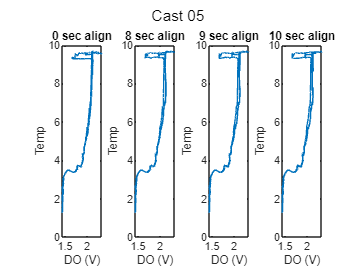

cast05 = align_CTD_KF(cast05,'Cast 05',a1,a2,a3);

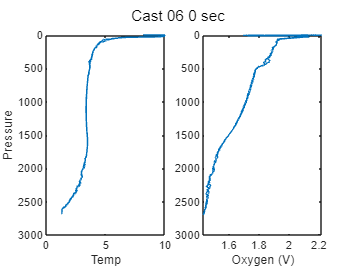

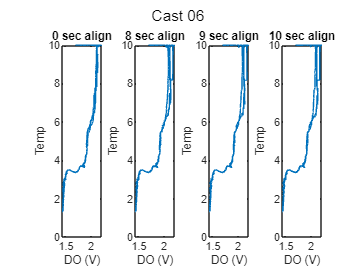

cast06 = align_CTD_KF(cast06,'Cast 06',a1,a2,a3);

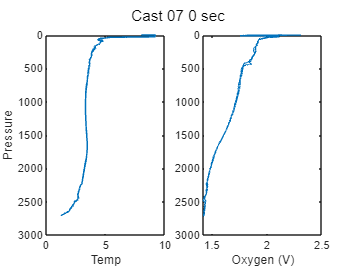

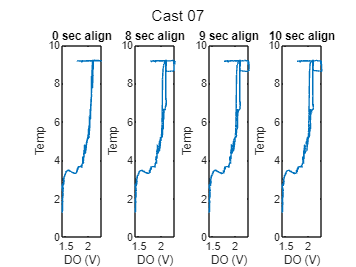

cast07 = align_CTD_KF(cast07,'Cast 07',a1,a2,a3);

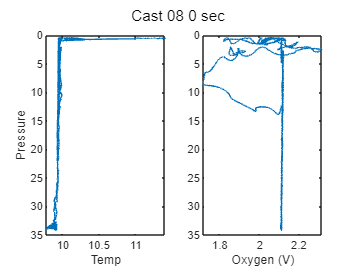

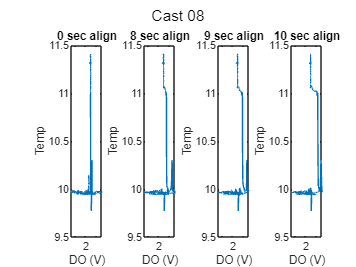

cast08 = align_CTD_KF(cast08,'Cast 08',a1,a2,a3);

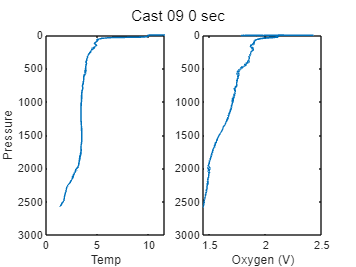

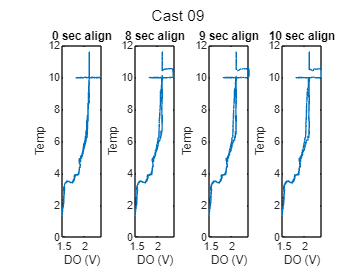

cast09 = align_CTD_KF(cast09,'Cast 09',a1,a2,a3);

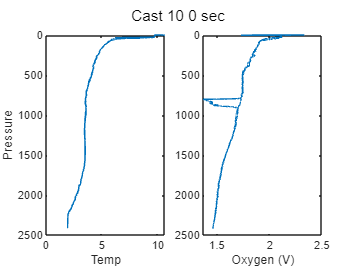

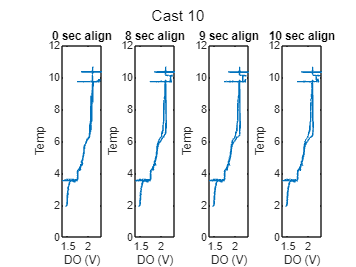

cast10 = align_CTD_KF(cast10,'Cast 10',a1,a2,a3);

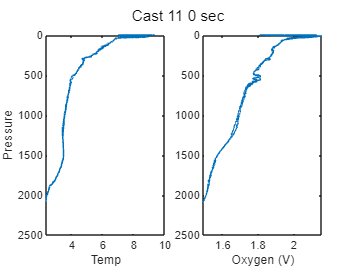

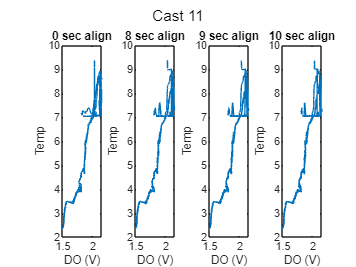

cast11 = align_CTD_KF(cast11,'Cast 11',a1,a2,a3);

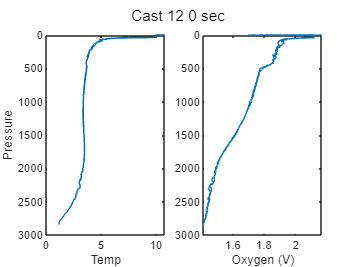

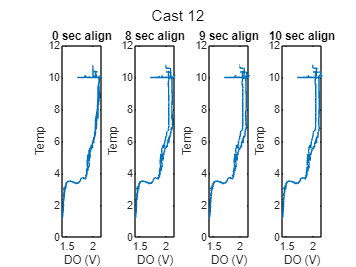

cast12 = align_CTD_KF(cast12,'Cast 12',a1,a2,a3);


% Pick align_sec

% a1 = 4;
align_sec = 8; 
clear cast*

### Use Bottle samples to calculate new SOC (gain) and E terms for CTD data 

CTD_sen = 1; % Use primary or secondary CTD temp and Sal 

% Create bottle summary file with CTD oxygen calculated using calibrated
% salinity product 
addpath('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year8')
addpath('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year8\Final_From_Leah')
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year8')

btl = readtable('Irminger_Sea-08_AR60-01_Summary_KF_badremoved.xlsx','TextType','string');
btl.Cast = double(btl.Cast); btl.Bottle = double(btl.Bottle);
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum01 = btl(btl.Cast == 1,:);
btlsum02 = btl(btl.Cast == 2,:);
btlsum04 = btl(btl.Cast == 4,:);
btlsum05 = btl(btl.Cast == 5,:);
btlsum06 = btl(btl.Cast == 6,:);
btlsum07 = btl(btl.Cast == 7,:);
btlsum09 = btl(btl.Cast == 9,:);
btlsum10 = btl(btl.Cast == 10,:);
btlsum11 = btl(btl.Cast == 11,:);
btlsum12 = btl(btl.Cast == 12,:);

% Had to change bottle numbers in csv files to be sequential 
% [btlsum] = combine_btl_files(leah_btl_file,btl_file,btlsum,CTD_sen)
btlsum01 = combine_btl_files('AR60-1_001.cbot_s','ar60-1_001.csv',btlsum01,CTD_sen);

btlsum02 = combine_btl_files('AR60-1_002.cbot_s','ar60-1_002.csv',btlsum02,CTD_sen);

btlsum04 = combine_btl_files('AR60-1_004.cbot_s','ar60-1_004.csv',btlsum04,CTD_sen);

btlsum05 = combine_btl_files('AR60-1_005.cbot_s','ar60-1_005.csv',btlsum05,CTD_sen);

btlsum06 = combine_btl_files('AR60-1_006.cbot_s','ar60-1_006.csv',btlsum06,CTD_sen);

btlsum07 = combine_btl_files('AR60-1_007.cbot_s','ar60-1_007.csv',btlsum07,CTD_sen);

btlsum09 = combine_btl_files('AR60-1_009.cbot_s','ar60-1_009.csv',btlsum09,CTD_sen);

btlsum10 = combine_btl_files('AR60-1_010.cbot_s','ar60-1_010.csv',btlsum10,CTD_sen);

btlsum11 = combine_btl_files('AR60-1_011.cbot_s','ar60-1_011.csv',btlsum11,CTD_sen);

btlsum12 = combine_btl_files('AR60-1_012.cbot_s','ar60-1_012.csv',btlsum12,CTD_sen);


btlsum0 = [btlsum01; btlsum02; btlsum04; btlsum05; btlsum06; btlsum07; btlsum09; btlsum10; btlsum11; btlsum12]; % casts that are being processed for E2 and gain together 
% btlsum0 = [btlsum04; btlsum05; btlsum06; btlsum07; btlsum12]; % casts that are being processed for E2 and gain together 

% figure
% plot(btlsum0.Winkler_mLL*44.661,btlsum0.PrDM,'ok')
% axis ij

% 
% Wink_low0 = find(btlsum0.Winkler_mLL*44.661 < 260);
% btlsum0.Winkler_mLL(Wink_low0) = NaN;

% figure
% plot(btlsum0.Winkler_mLL*44.661,btlsum0.PrDM,'ok')
% axis ij

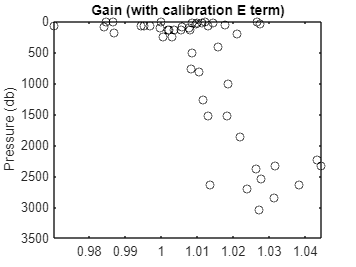



figure % Uses oxygen (ml/l) recalculated using Leah's finalized salinity product 
plot(btlsum0.Winkler_mLL./btlsum0.CTDoxy_mLL_cal,btlsum0.PrDM,'ok')
% hold on
% plot(btlsum10.Winkler_mLL./btlsum10.CTDoxy_mLL_hyst,btlsum10.PrDM,'go')
% plot(btlsum21.Winkler_mLL./btlsum21.CTDoxy_mLL_hyst,btlsum21.PrDM,'ro')
axis ij
ylabel('Pressure (db)')
title('Gain (with calibration E term)')


% gain0_threshold_low = 0.95;
% gain0 = btlsum0.Winkler_mLL./btlsum0.CTDoxy_mLL_cal;
% Wink_low = find(gain0_threshold_low > gain0);
% btlsum0.Winkler_mLL(Wink_low) = NaN;
% 
% % gain0_threshold_high = 1.04;
% % gain0 = btlsum0.Winkler_mLL./btlsum0.CTDoxy_mLL_cal;
% % Wink_high = find(gain0 > gain0_threshold_high);
% % btlsum0.Winkler_mLL(Wink_high) = NaN;
% 
% figure
% plot(btlsum0.Winkler_mLL./btlsum0.CTDoxy_mLL_cal,btlsum0.PrDM,'ok')
% axis ij
% ylabel('Pressure (db)')
% title('Gain (with calibration E term)')


% figure % Uses oxygen (ml/l) recalculated using Leah's finalized salinity product 
% subplot(1,2,1)
% plot(cast01.sbeox0mL_L,cast01.pm)
% hold on
% plot(btlsum01.Winkler_mLL,btlsum01.PrDM,'o')
% axis ij
% ylabel('Pressure (db)')
% 
% subplot(1,2,2)
% plot(btlsum01.Winkler_mLL./btlsum01.CTDoxy_mLL_cal,btlsum01.PrDM,'o')
% axis ij
% ylabel('Pressure (db)')
% title('Gain (with calibration E term)')
% title('Cast 01')
% 
% figure
% subplot(1,2,1)
% plot(cast02.sbeox0mL_L,cast02.pm)
% hold on
% plot(btlsum02.Winkler_mLL,btlsum02.PrDM,'o')
% axis ij
% ylabel('Pressure (db)')
% 
% subplot(1,2,2)
% plot(btlsum02.Winkler_mLL./btlsum02.CTDoxy_mLL_cal,btlsum02.PrDM,'o')
% axis ij
% ylabel('Pressure (db)')
% title('Gain (with calibration E term)')
% title('Cast 02')
% 
% figure
% subplot(1,2,1)
% plot(cast04.sbeox0mL_L,cast04.pm)
% hold on
% plot(btlsum04.Winkler_mLL,btlsum04.PrDM,'o')
% axis ij
% ylabel('Pressure (db)')
% 
% subplot(1,2,2)
% plot(btlsum04.Winkler_mLL./btlsum04.CTDoxy_mLL_cal,btlsum04.PrDM,'o')
% axis ij
% ylabel('Pressure (db)')
% title('Gain (with calibration E term)')
% title('Cast 04')
% 
% figure
% subplot(1,2,1)
% plot(cast05.sbeox0mL_L,cast05.pm)
% hold on
% plot(btlsum05.Winkler_mLL,btlsum05.PrDM,'o')
% axis ij
% ylabel('Pressure (db)')
% 
% subplot(1,2,2)
% plot(btlsum05.Winkler_mLL./btlsum05.CTDoxy_mLL_cal,btlsum05.PrDM,'o')
% axis ij
% ylabel('Pressure (db)')
% title('Gain (with calibration E term)')
% title('Cast 05')
% 
% figure
% subplot(1,2,1)
% plot(cast06.sbeox0mL_L,cast06.pm)
% hold on
% plot(btlsum06.Winkler_mLL,btlsum06.PrDM,'o')
% axis ij
% ylabel('Pressure (db)')
% 
% subplot(1,2,2)
% plot(btlsum06.Winkler_mLL./btlsum06.CTDoxy_mLL_cal,btlsum06.PrDM,'o')
% axis ij
% ylabel('Pressure (db)')
% title('Gain (with calibration E term)')
% title('Cast 06')
% 
% figure
% subplot(1,2,1)
% plot(cast07.sbeox0mL_L,cast07.pm)
% hold on
% plot(btlsum07.Winkler_mLL,btlsum07.PrDM,'o')
% axis ij
% ylabel('Pressure (db)')
% 
% subplot(1,2,2)
% plot(btlsum07.Winkler_mLL./btlsum07.CTDoxy_mLL_cal,btlsum07.PrDM,'o')
% axis ij
% ylabel('Pressure (db)')
% title('Gain (with calibration E term)')
% title('Cast 07')
% 
% figure
% subplot(1,2,1)
% plot(cast09.sbeox0mL_L,cast09.pm)
% hold on
% plot(btlsum09.Winkler_mLL,btlsum09.PrDM,'o')
% axis ij
% ylabel('Pressure (db)')
% 
% subplot(1,2,2)
% plot(btlsum09.Winkler_mLL./btlsum09.CTDoxy_mLL_cal,btlsum09.PrDM,'o')
% axis ij
% ylabel('Pressure (db)')
% title('Gain (with calibration E term)')
% title('Cast 09')
% 
% figure
% subplot(1,2,1)
% plot(cast10.sbeox0mL_L,cast10.pm)
% hold on
% plot(btlsum10.Winkler_mLL,btlsum10.PrDM,'o')
% axis ij
% ylabel('Pressure (db)')
% 
% subplot(1,2,2)
% plot(btlsum10.Winkler_mLL./btlsum10.CTDoxy_mLL_cal,btlsum10.PrDM,'o')
% axis ij
% ylabel('Pressure (db)')
% title('Gain (with calibration E term)')
% title('Cast 10')
% 
% figure
% subplot(1,2,1)
% plot(cast11.sbeox0mL_L,cast11.pm)
% hold on
% plot(btlsum11.Winkler_mLL,btlsum11.PrDM,'o')
% axis ij
% ylabel('Pressure (db)')
% 
% subplot(1,2,2)
% plot(btlsum11.Winkler_mLL./btlsum11.CTDoxy_mLL_cal,btlsum11.PrDM,'o')
% axis ij
% ylabel('Pressure (db)')
% title('Gain (with calibration E term)')
% title('Cast 11')
% 
% figure
% subplot(1,2,1)
% plot(cast12.sbeox0mL_L,cast12.pm)
% hold on
% plot(btlsum12.Winkler_mLL,btlsum12.PrDM,'o')
% axis ij
% ylabel('Pressure (db)')
% 
% subplot(1,2,2)
% plot(btlsum12.Winkler_mLL./btlsum12.CTDoxy_mLL_cal,btlsum12.PrDM,'o')
% title('Cast 12')
% axis ij
% ylabel('Pressure (db)')
% title('Gain (with calibration E term)')

% % Look at sensor quality for OOI Irminger Sea Located Casts
% figure
% % plot(cast01.t090C,cast01.sbeox0mL_L,'.')
% % hold on
% % plot(cast02.t090C,cast02.sbeox0mL_L,'.')
% % plot(cast03.t090C,cast03.sbeox0mL_L,'.')
% plot(cast04.t090C,cast04.sbeox0mL_L,'.')
% hold on
% plot(cast05.t090C,cast05.sbeox0mL_L,'.')
% plot(cast06.t090C,cast06.sbeox0mL_L,'.')
% plot(cast07.t090C,cast07.sbeox0mL_L,'.')
% % plot(cast09.t090C,cast09.sbeox0mL_L,'.')
% % plot(cast10.t090C,cast10.sbeox0mL_L,'.')
% % plot(cast11.t090C,cast11.sbeox0mL_L,'.')
% plot(cast12.t090C,cast12.sbeox0mL_L,'.')


% Same Oxygen Sensor for whole cruise 
% Calibration standards from SBE xmlcon file 

cal.SOC = double(6.57420e-001);
cal.VOFFSET = double(-4.92800e-001);
cal.A = double(-5.61700e-003);
cal.B = double(1.78090e-004);
cal.C = double(-2.43640e-006);
cal.E = double(3.60000e-002);
cal.Tau20 = double(1.34000e+000);
cal.INSTRUMENT_TYPE = 'SBE43';
cal.SERIALNO = '0444';
cal.OCALDATE = '08-Jul-21';

H = [-0.033, 5000, 1450]; % Default 

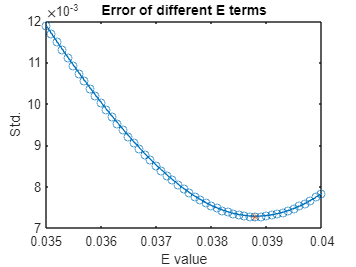

cal.E2 = 0.0388


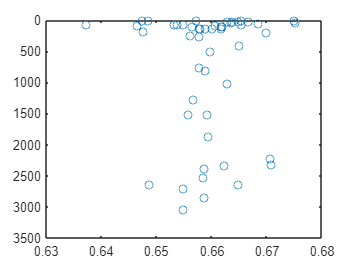

cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing') 
[cal] = E2_calculation(btlsum0,cal,CTD_sen); % Use dummy bottle summary with outlier removed

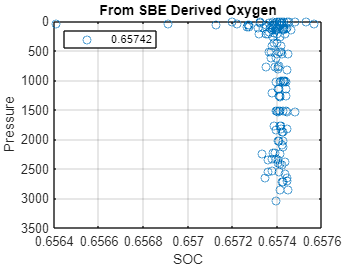

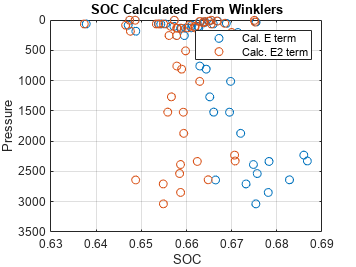

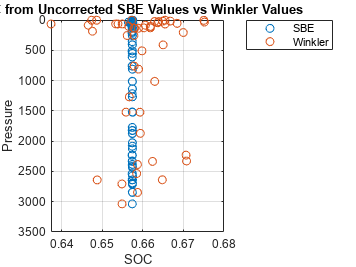

New SOC = 0.65957
EGain = 1.0033+/- 0.011082



[cal] = Gain_E2_Calculation(btlsum0,cal,CTD_sen); % Use dummy bottle summary with any outliers removed

### Combine Leah's processed cast files with my processed cast files 

% Read in processed casts
% Processed with 4 sec DO alignment and SBE default hysteresis, SOC, and E term
% 
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year8')
% Casts 
cast01u = readSBScnv( 'uar60-1_001.cnv' );
cast02u = readSBScnv( 'uar60-1_002.cnv' );
cast03u = readSBScnv( 'uar60-1_003.cnv' );
cast04u = readSBScnv( 'uar60-1_004.cnv' );
cast05u = readSBScnv( 'uar60-1_005.cnv' );
cast06u = readSBScnv( 'uar60-1_006.cnv' );
cast07u = readSBScnv( 'uar60-1_007.cnv' );
cast08u = readSBScnv( 'uar60-1_008.cnv' );
cast09u = readSBScnv( 'uar60-1_009.cnv' );
cast10u = readSBScnv( 'uar60-1_010.cnv' );
cast11u = readSBScnv( 'uar60-1_011.cnv' );
cast12u = readSBScnv( 'uar60-1_012.cnv' );

cast01d = readSBScnv( 'dar60-1_001.cnv' );
cast02d = readSBScnv( 'dar60-1_002.cnv' );
cast03d = readSBScnv( 'dar60-1_003.cnv' );
cast04d = readSBScnv( 'dar60-1_004.cnv' );
cast05d = readSBScnv( 'dar60-1_005.cnv' );
cast06d = readSBScnv( 'dar60-1_006.cnv' );
cast07d = readSBScnv( 'dar60-1_007.cnv' );
cast08d = readSBScnv( 'dar60-1_008.cnv' );
cast09d = readSBScnv( 'dar60-1_009.cnv' );
cast10d = readSBScnv( 'dar60-1_010.cnv' );
cast11d = readSBScnv( 'dar60-1_011.cnv' );
cast12d = readSBScnv( 'dar60-1_012.cnv' );


cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year8\Final_From_Leah')
load ar60-01_final.mat

% Combine leah's finalized product with my oxygen file 
% function [cast,cast0] = combine_CTD_files(leah_cast,cast,CTD_sen)

% [cast01u, cast01u0] = combine_CTD_files(ar60_001u,cast01u,CTD_sen); [cast01d, cast01d0] = combine_CTD_files(ar60_001d,cast01d,CTD_sen);  
% [cast02u, cast02u0] = combine_CTD_files(ar60_002u,cast02u,CTD_sen); [cast02d, cast02d0] = combine_CTD_files(ar60_002d,cast02d,CTD_sen);  
% [cast03u, cast03u0] = combine_CTD_files(ar60_003u,cast03u,CTD_sen); [cast03d, cast03d0] = combine_CTD_files(ar60_003d,cast03d,CTD_sen);  
% [cast04u, cast04u0] = combine_CTD_files(ar60_004u,cast04u,CTD_sen); [cast04d, cast04d0] = combine_CTD_files(ar60_004d,cast04d,CTD_sen);  
% [cast05u, cast05u0] = combine_CTD_files(ar60_005u,cast05u,CTD_sen); [cast05d, cast05d0] = combine_CTD_files(ar60_005d,cast05d,CTD_sen);  
% [cast06u, cast06u0] = combine_CTD_files(ar60_006u,cast06u,CTD_sen); [cast06d, cast06d0] = combine_CTD_files(ar60_006d,cast06d,CTD_sen);  
% [cast07u, cast07u0] = combine_CTD_files(ar60_007u,cast07u,CTD_sen); [cast07d, cast07d0] = combine_CTD_files(ar60_007d,cast07d,CTD_sen);  
% [cast08u, cast08u0] = combine_CTD_files(ar60_008u,cast08u,CTD_sen); [cast08d, cast08d0] = combine_CTD_files(ar60_008d,cast08d,CTD_sen);  
% [cast09u, cast09u0] = combine_CTD_files(ar60_009u,cast09u,CTD_sen); [cast09d, cast09d0] = combine_CTD_files(ar60_009d,cast09d,CTD_sen);  
% [cast10u, cast10u0] = combine_CTD_files(ar60_010u,cast10u,CTD_sen); [cast10d, cast10d0] = combine_CTD_files(ar60_010d,cast10d,CTD_sen);  
% [cast11u, cast11u0] = combine_CTD_files(ar60_011u,cast11u,CTD_sen); [cast11d, cast11d0] = combine_CTD_files(ar60_011d,cast11d,CTD_sen);  
% [cast12u, cast12u0] = combine_CTD_files(ar60_012u,cast12u,CTD_sen); [cast12d, cast12d0] = combine_CTD_files(ar60_012d,cast12d,CTD_sen);    

[cast01u, ~] = combine_CTD_files(ar60_001u,cast01u,CTD_sen); [cast01d, ~] = combine_CTD_files(ar60_001d,cast01d,CTD_sen);  
[cast02u, ~] = combine_CTD_files(ar60_002u,cast02u,CTD_sen); [cast02d, ~] = combine_CTD_files(ar60_002d,cast02d,CTD_sen);  
[cast03u, ~] = combine_CTD_files(ar60_003u,cast03u,CTD_sen); [cast03d, ~] = combine_CTD_files(ar60_003d,cast03d,CTD_sen);  
[cast04u, ~] = combine_CTD_files(ar60_004u,cast04u,CTD_sen); [cast04d, ~] = combine_CTD_files(ar60_004d,cast04d,CTD_sen);  
[cast05u, ~] = combine_CTD_files(ar60_005u,cast05u,CTD_sen); [cast05d, ~] = combine_CTD_files(ar60_005d,cast05d,CTD_sen);  
[cast06u, ~] = combine_CTD_files(ar60_006u,cast06u,CTD_sen); [cast06d, ~] = combine_CTD_files(ar60_006d,cast06d,CTD_sen);  
[cast07u, ~] = combine_CTD_files(ar60_007u,cast07u,CTD_sen); [cast07d, ~] = combine_CTD_files(ar60_007d,cast07d,CTD_sen);  
[cast08u, ~] = combine_CTD_files(ar60_008u,cast08u,CTD_sen); [cast08d, ~] = combine_CTD_files(ar60_008d,cast08d,CTD_sen);  
[cast09u, ~] = combine_CTD_files(ar60_009u,cast09u,CTD_sen); [cast09d, ~] = combine_CTD_files(ar60_009d,cast09d,CTD_sen);  
[cast10u, ~] = combine_CTD_files(ar60_010u,cast10u,CTD_sen); [cast10d, ~] = combine_CTD_files(ar60_010d,cast10d,CTD_sen);  
[cast11u, ~] = combine_CTD_files(ar60_011u,cast11u,CTD_sen); [cast11d, ~] = combine_CTD_files(ar60_011d,cast11d,CTD_sen);  
[cast12u, ~] = combine_CTD_files(ar60_012u,cast12u,CTD_sen); [cast12d, ~] = combine_CTD_files(ar60_012d,cast12d,CTD_sen);    

### Correct casts using new SOC term, E term, and Leah's calibrated salinity product

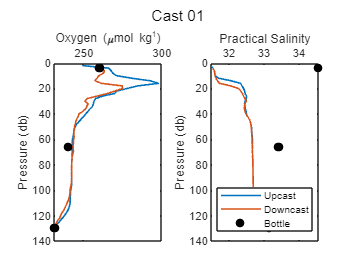

sal_plots = 1; leah_plot = 0; 
% [castu, castd, btlsum] = Process_Cast_Gain_E2_v2(castu,castd,cal,btlsum,sal_plots,leah_plots,CTD_sen,CastString)
[cast01u, cast01d, btlsum01] = Process_Cast_Gain_E2_v2(cast01u,cast01d,cal,btlsum01,sal_plots,leah_plot,CTD_sen,'Cast 01');

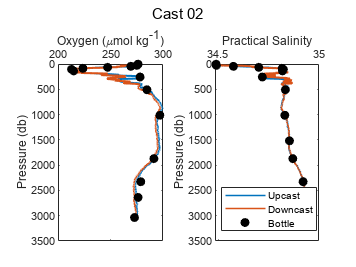

[cast02u, cast02d, btlsum02] = Process_Cast_Gain_E2_v2(cast02u,cast02d,cal,btlsum02,sal_plots,leah_plot,CTD_sen,'Cast 02');

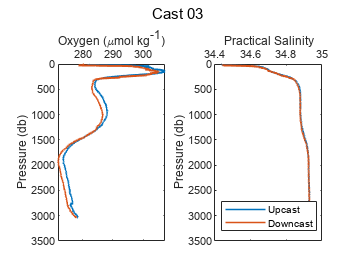

[cast03u, cast03d, btlsum03] = Process_Cast_Gain_E2_v2(cast03u,cast03d,cal,0,sal_plots,leah_plot,CTD_sen,'Cast 03');

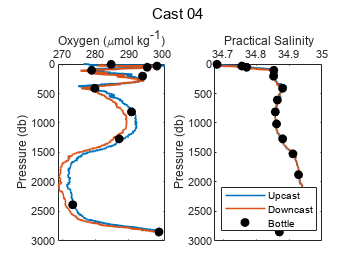

[cast04u, cast04d, btlsum04] = Process_Cast_Gain_E2_v2(cast04u,cast04d,cal,btlsum04,sal_plots,leah_plot,CTD_sen,'Cast 04');

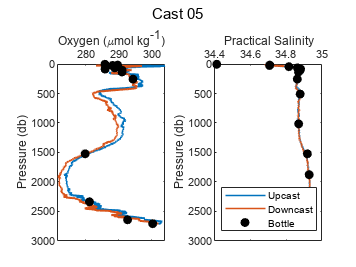

[cast05u, cast05d, btlsum05] = Process_Cast_Gain_E2_v2(cast05u,cast05d,cal,btlsum05,sal_plots,leah_plot,CTD_sen,'Cast 05');

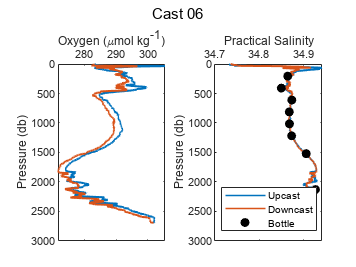

[cast06u, cast06d, btlsum06] = Process_Cast_Gain_E2_v2(cast06u,cast06d,cal,btlsum06,sal_plots,leah_plot,CTD_sen,'Cast 06');

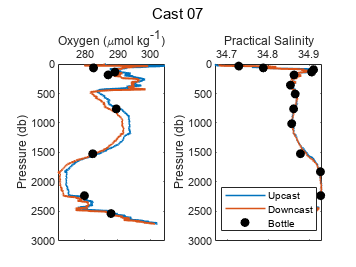

[cast07u, cast07d, btlsum07] = Process_Cast_Gain_E2_v2(cast07u,cast07d,cal,btlsum07,sal_plots,leah_plot,CTD_sen,'Cast 07');

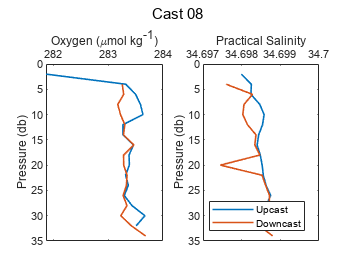

[cast08u, cast08d, btlsum08] = Process_Cast_Gain_E2_v2(cast08u,cast08d,cal,0,sal_plots,leah_plot,CTD_sen,'Cast 08');

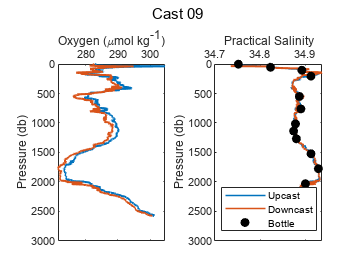

[cast09u, cast09d, btlsum09] = Process_Cast_Gain_E2_v2(cast09u,cast09d,cal,btlsum09,sal_plots,leah_plot,CTD_sen,'Cast 09');

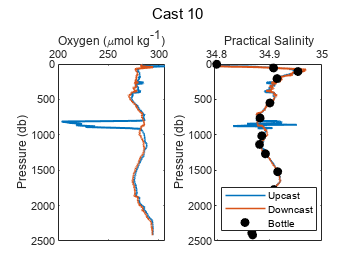

[cast10u, cast10d, btlsum10] = Process_Cast_Gain_E2_v2(cast10u,cast10d,cal,btlsum10,sal_plots,leah_plot,CTD_sen,'Cast 10'); 

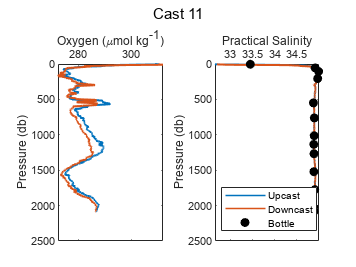

[cast11u, cast11d, btlsum11] = Process_Cast_Gain_E2_v2(cast11u,cast11d,cal,btlsum11,sal_plots,leah_plot,CTD_sen,'Cast 11');

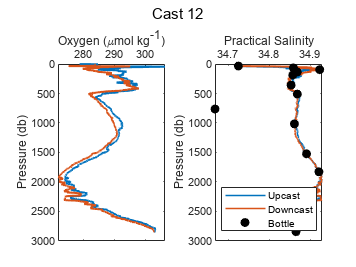

[cast12u, cast12d, btlsum12] = Process_Cast_Gain_E2_v2(cast12u,cast12d,cal,btlsum12,sal_plots,leah_plot,CTD_sen,'Cast 12');

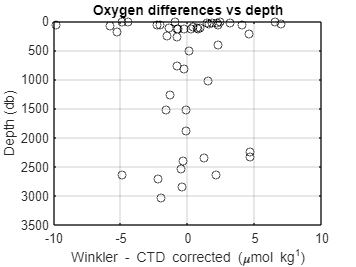

btlsum_yr8 = [btlsum01; btlsum02; btlsum04; btlsum05; btlsum06; btlsum07; btlsum09;...
    btlsum10; btlsum11; btlsum12];

btlsum_yr8_OOI = [btlsum04; btlsum05; btlsum06; btlsum07; btlsum12];

oxy_diff = btlsum_yr8.Winkler_umolkg-btlsum_yr8.DOcorr_umolkg;

figure
plot(oxy_diff,btlsum_yr8.prs,'ok')
axis ij
grid on
ylabel('Depth (db)')
xlabel('Winkler - CTD corrected (\mumol kg^-^1)')
title('Oxygen differences vs depth')

disp(['DO align (s) = ' num2str(align_sec)])

DO align (s) = 8


disp(['Cal. E term = ' num2str(cal.E)])

Cal. E term = 0.036


disp(['Adjust. E term (E2) = ' num2str(cal.E2)])

Adjust. E term (E2) = 0.0388



disp(['Cal SOC = ' num2str(cal.SOC)])

Cal SOC = 0.65742


disp(['New SOC = ' num2str(cal.SOCnew) ])

New SOC = 0.65957


disp(['E2Gain = ' num2str(cal.E2gain) '+/- ' num2str(cal.E2gainSTD)])

E2Gain = 1.0033+/- 0.011082


% run('Year8_PT_DO_plots.m')

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year8')
clear btlsum0 btl
dt_Processed = datetime;
save Year8_Processed_KF cast* btl* cal* dt_Processed 